# ME/SE 701 project

Paper:$H_{\infty }$/LQR Optimal COntrol for a Supersonic Air-Breathing Missile of Asymmetric Configuration

rng(1,'twister');
unc = 30

unc = 30

## Symbol definitions from paper

- Symbol - Discription - Unit - Variable

- $x,y,z$ - Cartesian body axes - m - x_axis,y_axis,z_axis

syms x_axis
syms y_axis 
syms z_axis

- $v,w$ - Translational velocity (y_axis,z_axis respectivly) - m/s - v,w

v = 1;
w = 1;

- $p,q,r$ - Rotational velocity about $x,y,z$ axes - rad/s - p,q,r

p = 0;
q = 0;
r = 0;

- $U$- Constant forward velocity - m/s - U

U = 1029

U = 1029

Uu = ureal('U',1029,'percentage',5); % mach 3

- $\xi ,\eta ,\zeta$ - Aileron, Elevator and Rudder deflection - radians - xi,eta,zeta

xi   = 0;
eta  = 0;
zeta = 0;

- $\alpha$ - Angle of attack - radians - alpha

alpha = 0;
alphau = ureal('alpha',.2,'percentage',unc); % assume about same axis as q

- $\beta \;$- Sideslip angle - radians - beta

beta = 0;
betau = ureal('beta',.2,'percentage',unc); % assume about same axis as r

- $\phi$- Roll angle - radians - phi

phi = 0; % assume about same axis as p

- $a_y ,a_z$ - Accelerations along y ans z axes, respectively - $\frac{m}{s^2 }$ - a_y,a_z

a_y = 0; % assume along the y axis
a_z = 0; % assume along the z axis

- $\gamma$ - Controller performance metric - unitless - gamma

gamma = 0.7585; % given in the paper

- $l_i ,m_i ,n_i$ - partial derivatives of roll, pitch, yaw angular accelerations about i - mixed - l_i,m_i,n_i

-      note for these X = [X_p,X_q,X_r,X_w,X_v,X_xi,X_eta,X_zeta]

L = get_partials([1,10,10,0.01,0.01,2,2,2]);
M = get_partials([1,10,10,0.01,0.01,2,2,2]);
N = get_partials([1,10,10,0.01,0.01,2,2,2]);
Lu = get_partials([ureal('L1',1,'percentage',unc),ureal('L2',10,'percentage',unc),ureal('L3',10,'percentage',unc),ureal('L4',0.01,'percentage',unc),ureal('L5',0.01,'percentage',unc),ureal('L6',2,'percentage',unc),ureal('L7',2,'percentage',unc),ureal('L8',2,'percentage',unc)]);
Mu = get_partials([ureal('M1',1,'percentage',unc),ureal('M2',10,'percentage',unc),ureal('M3',10,'percentage',unc),ureal('M4',0.01,'percentage',unc),ureal('M5',0.01,'percentage',unc),ureal('M6',2,'percentage',unc),ureal('M7',2,'percentage',unc),ureal('M8',2,'percentage',unc)]);
Nu = get_partials([ureal('N1',1,'percentage',unc),ureal('N2',10,'percentage',unc),ureal('N3',10,'percentage',unc),ureal('N4',0.01,'percentage',unc),ureal('N5',0.01,'percentage',unc),ureal('N6',2,'percentage',unc),ureal('N7',2,'percentage',unc),ureal('N8',2,'percentage',unc)]);

- $y_i ,z_i$ - partial derivatives of translational accelerations about i along repective acces -mixed - y_i,z_i

Y = get_partials([1,10,10,100,100,2,2,2]);
Z = get_partials([1,10,10,100,100,2,2,2]);
Yu = get_partials([ureal('Y1',1,'percentage',unc),ureal('Y2',10,'percentage',unc),ureal('Y3',10,'percentage',unc),ureal('Y4',100,'percentage',unc),ureal('Y5',100,'percentage',unc),ureal('Y6',2,'percentage',unc),ureal('Y7',2,'percentage',unc),ureal('Y8',2,'percentage',unc)]);
Zu = get_partials([ureal('Z1',1,'percentage',unc),ureal('Z2',10,'percentage',unc),ureal('Z3',10,'percentage',unc),ureal('Z4',100,'percentage',unc),ureal('Z5',100,'percentage',unc),ureal('Z6',2,'percentage',unc),ureal('Z7',2,'percentage',unc),ureal('Z8',2,'percentage',unc)]);

- Q - LQR gain provided - mixed - Q_provided

Q_provided = diag([1,10,10,0.01,0.01]);

- R - LQR gain provided - mixed - R_provided

R_provided = eye(3)

R_provided =      1     0     0
     0     1     0
     0     0     1


- $W_e \left(S\right)$ - H infinity gain proformance - mixed - W_e

for i = 1:5
    for j = 1:5
        W_e_numd{i,j} = [0];
        W_e_demd{i,j} = [1];
    end
end
%1,1
W_e_numd{1,1} = [1,10];
W_e_demd{1,1} = [2,0.1];
%4,4
W_e_numd{4,4} = [1,4];
W_e_demd{4,4} = [2,0.04];
%5,5
W_e_numd{5,5} = [1,4];
W_e_demd{5,5} = [2,0.04];
% make tf
W_e = tf(W_e_numd,W_e_demd)


W_e =
 
  From input 1 to output...
        s + 10
   1:  ---------
       2 s + 0.1
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
  From input 2 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
         s + 4
   4:  ----------
       2 s + 0.04
 
   5:  0
 
  From input 5 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
         s + 4
   5:  ----------
       2 s + 0.04
 
Continuous-time transfer function.



- $W_u \left(S\right)$ - H infinity gain control - mixed - W_u

for i = 1:3
    for j = 1:3
        W_u_numd{i,j} = [0];
        W_u_demd{i,j} = [1];
    end
end
%1,1
W_u_numd{1,1} = [1,0.009425];
W_u_demd{1,1} = [0.0001,94.25];
%4,4
W_u_numd{2,2} = [1,0.009425];
W_u_demd{2,2} = [0.0001,94.25];
%5,5
W_u_numd{3,3} = [1,0.009425];
W_u_demd{3,3} = [0.0001,94.25];
% make tf
W_u = tf(W_u_numd,W_u_demd)


W_u =
 
  From input 1 to output...
         s + 0.009425
   1:  ----------------
       0.0001 s + 94.25
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
         s + 0.009425
   2:  ----------------
       0.0001 s + 94.25
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
         s + 0.009425
   3:  ----------------
       0.0001 s + 94.25
 
Continuous-time transfer function.



## Define LTI system

A = get_A(L,M,N,Y,Z,U,alpha,beta)

A = 	1.0e+03 *

    0.0004    0.0072    0.0000    0.0000    0.0000
    0.0004    0.0054    0.0042    0.0000    0.0000
    0.0004    0.0056    0.0014    0.0000    0.0000
    0.0003    0.0013   -1.0288    0.0679    0.0212
    0.0006    1.0305    0.0059    0.0700    0.0102


B = get_B(L,M,N,Y,Z)

B =     0.1847    0.3725    0.6911
    1.7562    0.0548    1.3409
    1.9365    0.6268    1.3846
    0.5311    0.9831    0.1067
    0.8281    1.3888    0.8284


C = get_C(Y,Z)

C =     1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0   67.8836   21.1628
         0         0         0   69.9758   10.2334


D = get_D(Y,Z)

D =          0         0         0
         0         0         0
         0         0         0
    0.5311    0.9831    0.1067
    0.8281    1.3888    0.8284



Au = get_A(Lu,Mu,Nu,Yu,Zu,Uu,alphau,betau)


Au =

  Uncertain matrix with 5 rows and 5 columns.
  The uncertainty consists of the following blocks:
    L1: Uncertain real, nominal = 1, variability = [-30,30]%, 1 occurrences
    L2: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    L3: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    L4: Uncertain real, nominal = 0.01, variability = [-30,30]%, 1 occurrences
    L5: Uncertain real, nominal = 0.01, variability = [-30,30]%, 1 occurrences
    M1: Uncertain real, nominal = 1, variability = [-30,30]%, 1 occurrences
    M2: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    M3: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    M4: Uncertain real, nominal = 0.01, variability = [-30,30]%, 1 occurrences
    M5: Uncertain real, nominal = 0.01, variability = [-30,30]%, 1 occurrences
    N1: Uncertain real, nominal = 1, variability = [-30,30]%, 1 occurrences
    N2: Uncertain real, nominal = 10, varia

Bu = get_B(Lu,Mu,Nu,Yu,Zu)


Bu =

  Uncertain matrix with 5 rows and 3 columns.
  The uncertainty consists of the following blocks:
    L6: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    L7: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    L8: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    M6: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    M7: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    M8: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    N6: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    N7: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    N8: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Y6: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Y7: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Y8: Uncertain real, nominal = 2, variability = [-30,30]

Cu = get_C(Yu,Zu)


Cu =

  Uncertain matrix with 5 rows and 5 columns.
  The uncertainty consists of the following blocks:
    Y4: Uncertain real, nominal = 100, variability = [-30,30]%, 1 occurrences
    Y5: Uncertain real, nominal = 100, variability = [-30,30]%, 1 occurrences
    Z4: Uncertain real, nominal = 100, variability = [-30,30]%, 1 occurrences
    Z5: Uncertain real, nominal = 100, variability = [-30,30]%, 1 occurrences

Type "Cu.NominalValue" to see the nominal value, "get(Cu)" to see all properties, and "Cu.Uncertainty" to interact with the uncertain elements.



Du = get_D(Yu,Zu)


Du =

  Uncertain matrix with 5 rows and 3 columns.
  The uncertainty consists of the following blocks:
    Y6: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Y7: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Y8: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Z6: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Z7: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    Z8: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences

Type "Du.NominalValue" to see the nominal value, "get(Du)" to see all properties, and "Du.Uncertainty" to interact with the uncertain elements.




plant_raw = ss(A,B,C,D);
[plant] = get_plant_model(A,B,C,D)


plant =
 
  A = 
             x_p       x_q       x_r       x_w       x_v
   x_p     0.417     7.203  0.001144  0.003023  0.001468
   x_q    0.3968     5.388     4.192  0.006852  0.002045
   x_r    0.4173     5.587     1.404  0.001981  0.008007
   x_w    0.2878       1.3     -1029     67.88     21.16
   x_v    0.5741      1030     5.893     69.98     10.23
 
  B = 
             xi      eta     zeta
   x_p   0.1847   0.3725   0.6911
   x_q    1.756  0.05478    1.341
   x_r    1.937   0.6268    1.385
   x_w   0.5311   0.9831   0.1067
   x_v   0.8281    1.389   0.8284
 
  C = 
          x_p    x_q    x_r    x_w    x_v
   p        1      0      0      0      0
   q        0      1      0      0      0
   r        0      0      1      0      0
   ay       0      0      0  67.88  21.16
   az       0      0      0  69.98  10.23
   x_p      1      0      0      0      0
   x_q      0      1      0      0      0
   x_r      0      0      1      0      0
   x_w      0      0      0      1      

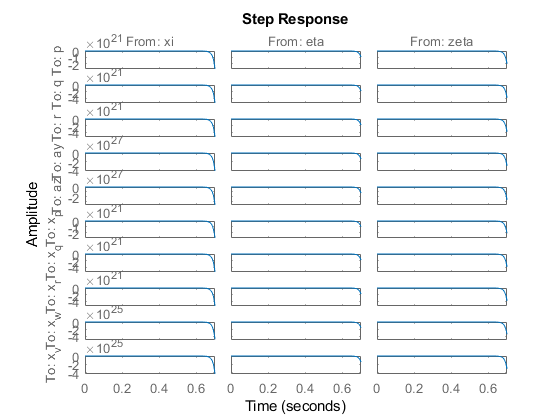

G_plant = tf(plant);
step(plant)

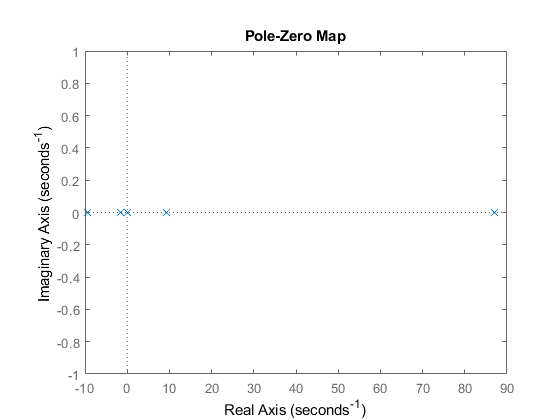

pzplot(plant)

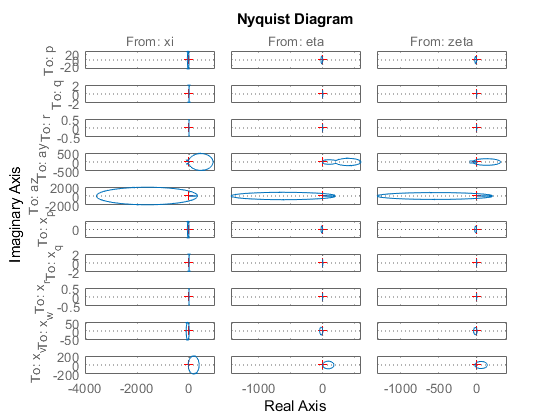

nyquist(plant)

### LQR controler

[K,S,e] = lqr(plant,Q_provided,R_provided,zeros(5,3))

K =    -0.8355  -31.7889   97.2116   -8.6301   -2.3977
   -1.0265  -16.6100   40.8737   -3.5709   -0.9974
    0.7327  -19.9848   66.1088   -5.9964   -1.6684


S =     1.9792    2.8750   -3.2631    0.0965    0.0212
    2.8750   20.8900  -36.8650    3.1143    0.8797
   -3.2631  -36.8650   86.9237   -7.5676   -2.1165
    0.0965    3.1143   -7.5676    0.7028    0.1983
    0.0212    0.8797   -2.1165    0.1983    0.0564


e =   -1.1835 + 0.0000i
  -1.7148 + 0.0000i
 -16.5212 +11.5365i
 -16.5212 -11.5365i
 -87.0905 + 0.0000i



[plant_augment] = get_plant_model(A,B,C,D);
[LQR_control] = get_state_feedback_control(K)


LQR_control =
 
  A = 
         fake
   fake     0
 
  B = 
         x_p  x_q  x_r  x_w  x_v
   fake    0    0    0    0    0
 
  C = 
         fake
   xi       0
   eta      0
   zeta     0
 
  D = 
             x_p      x_q      x_r      x_w      x_v
   xi    -0.8355   -31.79    97.21    -8.63   -2.398
   eta    -1.026   -16.61    40.87   -3.571  -0.9974
   zeta   0.7327   -19.98    66.11   -5.996   -1.668
 
Continuous-time state-space model.



plant_CL = feedback(plant_augment,LQR_control,'name',-1);

report = test_plant(plant_CL)

report = struct with fields:
            stepinfo: [10×3 struct]
    HistSettlingTime: 'Expected input number 2, m, to be integer-valued.'
         nyquistPlot: [10×3×268 double]
         systemPoles: [6×1 double]
         systemZeros: 0


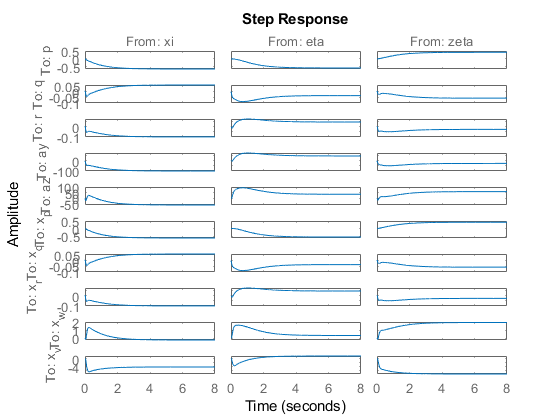

step(plant_CL)

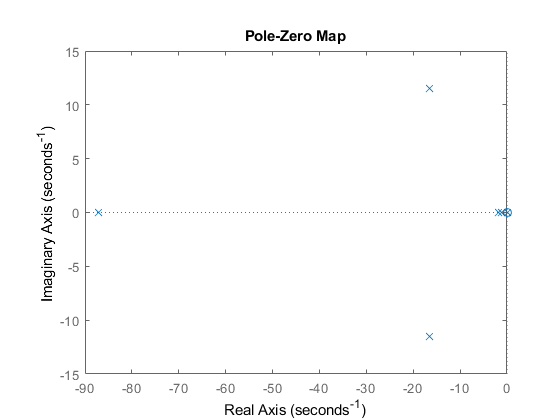

pzplot(plant_CL)

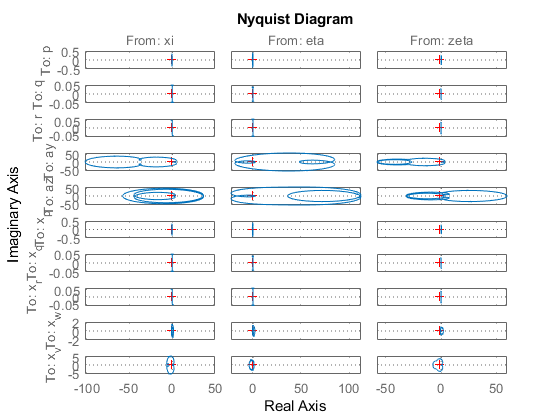

nyquist(plant_CL)

### Perturbed plant

%perturbed plant
[plant_augment] = get_plant_model(A,B,C,D);
[LQR_control] = get_state_feedback_control(K)


LQR_control =
 
  A = 
         fake
   fake     0
 
  B = 
         x_p  x_q  x_r  x_w  x_v
   fake    0    0    0    0    0
 
  C = 
         fake
   xi       0
   eta      0
   zeta     0
 
  D = 
             x_p      x_q      x_r      x_w      x_v
   xi    -0.8355   -31.79    97.21    -8.63   -2.398
   eta    -1.026   -16.61    40.87   -3.571  -0.9974
   zeta   0.7327   -19.98    66.11   -5.996   -1.668
 
Continuous-time state-space model.



plant_perturbed_CL = feedback(plant_augment,LQR_control,'name',-1);


### Hinf (on open loop plant)

%K_inf = get_Hinf(plant)
Wu_ss = ss(W_u);
Awu = Wu_ss.A./10000;
Bwu = Wu_ss.B./10000;
Cwu = Wu_ss.C./10000;
Dwu = Wu_ss.D./10000;
We_ss = ss(W_e);
Awe = We_ss.A.*.01;
Bwe = We_ss.B.*.01;
Cwe = We_ss.C.*.01;
Dwe = We_ss.D.*.01;
%P = [W_e -W_e*G_raw;zeros(3,5),W_u; eye(5),-G_raw]
%P = [A zeros(5,3) zeros(5,5) B; -Bwe*C Awe Bwe -Bwe*D; -Dwe*C Cwe Dwe -Dwe*D; zeros(3,5) zeros(3,3) zeros(3,5) eye(3); -C zeros(5,3) eye(5) -D];
P = [Au zeros(5,3) zeros(5,3) zeros(5,5) Bu; -Bwe*C Awe zeros(3,3) Bwe -Bwe*D; zeros(3,5) zeros(3,3) Awu zeros(3,5) Bwu; -Dwe*Cu Cwe zeros(5,3) Dwe -Dwe*Du; zeros(3,5) zeros(3,3) Cwu zeros(3,5) Dwu; -Cu zeros(5,3) zeros(5,3) eye(5) -Du]


P =

  Uncertain matrix with 24 rows and 19 columns.
  The uncertainty consists of the following blocks:
    L1: Uncertain real, nominal = 1, variability = [-30,30]%, 1 occurrences
    L2: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    L3: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    L4: Uncertain real, nominal = 0.01, variability = [-30,30]%, 1 occurrences
    L5: Uncertain real, nominal = 0.01, variability = [-30,30]%, 1 occurrences
    L6: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    L7: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    L8: Uncertain real, nominal = 2, variability = [-30,30]%, 1 occurrences
    M1: Uncertain real, nominal = 1, variability = [-30,30]%, 1 occurrences
    M2: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    M3: Uncertain real, nominal = 10, variability = [-30,30]%, 1 occurrences
    M4: Uncertain real, nominal = 0.01, variabil

Ptf = tf(P);
[Gc,G,gamma]=hinfsyn(Ptf,3,5)


Gc =
 
  D = 
            u1       u2       u3
   y1    12.89   -4.202    2.901
   y2    17.16   -2.353    2.038
   y3   -2.657   0.4391  -0.1935
   y4   -1.341   0.9892  -0.4301
   y5    8.154   0.9307  -0.3931
 
Static gain.


G =
 
  D = 
               u1         u2         u3         u4         u5         u6         u7         u8         u9        u10        u11
   y1      0.8764      8.946     -3.983     -5.039     -29.82          0          0          0          0          0          0
   y2      0.9579      5.332     -4.382     -5.942     -37.28          0          0          0          0          0          0
   y3      0.9889      7.482     -1.718     -8.038     -46.45          0          0          0          0          0          0
   y4       205.8      5.359      -1023      43.79      51.28          0          0          0          0          0          0
   y5      -205.7       1037     -9.175      7.735      38.87          0          0          0          0          0 

gamma = 1.0678e+03

### Cascade control

hinf must be based on plant_CL

### Disterbances

commandError = struct('xi',0.005,'eta',0.005,'zeta',0.005)

commandError = struct with fields:
      xi: 0.0050
     eta: 0.0050
    zeta: 0.0050


disterbance.time = struct('x_p',10,'x_q',20,'x_r',30,'x_w',40,'x_v',50)

disterbance = struct with fields:
        time: [1×1 struct]
        size: [1×1 struct]
    duration: 5


disterbance.size = struct('x_p',1,'x_q',1,'x_r',1,'x_w',1,'x_v',1)

disterbance = struct with fields:
        time: [1×1 struct]
        size: [1×1 struct]
    duration: 5


disterbance.duration = 5;
MeasurementNoise = struct('x_p',0.05,'x_q',0.05,'x_r',0.05,'x_w',0.05,'x_v',0.05)

MeasurementNoise = struct with fields:
    x_p: 0.0500
    x_q: 0.0500
    x_r: 0.0500
    x_w: 0.0500
    x_v: 0.0500



VC_Disterbance = 1

VC_Disterbance = 1

VC_Disterbance_Pulse = Simulink.Variant('VC_Disterbance==1')


VC_Disterbance_Pulse =

Simulink.Variant
    Condition: 'VC_Disterbance==1'



VC_Disterbance_Step  = Simulink.Variant('VC_Disterbance==2')


VC_Disterbance_Step =

Simulink.Variant
    Condition: 'VC_Disterbance==2'



- A,B,C,D - state space description - mixed metric standard - A,B,C,D

function A = get_A(L,M,N,Y,Z,U,alpha,beta)
%% creates the A matrix for the BTT missile based on source paper
A = [L(1:5);M(1:5);N(1:5);Y(1:5);Z(1:5)];
A(4,1) = A(4,1) + alpha * U;
A(5,1) = A(5,1) - beta*U;
A(5,2) = A(5,2) + U;
A(4,3) = A(4,3) - U;
end

function B = get_B(L,M,N,Y,Z)
%% creates the B matrix for the BTT missile based on source paper
B = [L(6:8);M(6:8);N(6:8);Y(6:8);Z(6:8)];
end

function C = get_C(Y,Z)
%% creates the C matrix for the BTT missile based on source paper
C = blkdiag(eye(3),[Y(4:5);Z(4:5)]);
end

function D = get_D(Y,Z)
%% creates the D matrix for the BTT misile based on source paper
D = [zeros(3,3);Y(6:8);Z(6:8)];
end

function [Ca,Da] = get_augment_output(C,D)
%% caluclates updated C and D matrixes to chagne the output equation to include the state
    Ca = [C;eye(size(C))];
    Da = [D;zeros(size(C,1),size(D,2))];
end

function [plant] = get_plant_model(A,B,C,D)
    [Ca,Da] = get_augment_output(C,D);
    plant = ss(A,B,Ca,Da);
    plant.InputName = {'xi','eta','zeta'};
    plant.OutputName = {'p','q','r','ay','az','x_p','x_q','x_r','x_w','x_v'};
    plant.StateName = {'x_p','x_q','x_r','x_w','x_v'};
end

function [controller] = get_state_feedback_control(K)
    controller = ss(0,zeros(1,5),zeros(3,1),K);
    controller.InputName = {'x_p','x_q','x_r','x_w','x_v'};
    controller.StateName = {'fake'};
    controller.OutputName = {'xi','eta','zeta'};
end

- X - state vector ${\left\lbrack p,q,r,w,v\right\rbrack }^T$ - mixed metric standard - x

function x = get_x(p,q,r,w,v)
    x=[p,q,r,w,v]';
end

- u - control vector ${\left\lbrack \xi \;,\eta \;,\zeta \right\rbrack }^T$ - mixed metric standard - u

function u = get_u(xi,eta,zeta)
    u=[xi,eta,zeta]';
end

- $K_s$ - LQR gain - mixed - K_s

function K_s = get_K_s(R,B,Ricatti)
    K_s = inv(R)*B'*Ricatti;
end

- $K_p$ - $H_{\infty }$ gain - mixed - K_p

- $P\left(s\right)$ - state space realisation of general plant - mixed - P_a

## Get partial derivative array

X = [X_p,X_q,X_r,X_w,X_v,X_xi,X_eta,X_zeta]

function dxdx = get_partials(scaleing)
% about rotational velocities
X_p = rand(1)*scaleing(1);
X_q = rand(1)*scaleing(2);
X_r = rand(1)*scaleing(3);
% about translational velocities
X_w = rand(1)*scaleing(4);
X_v = rand(1)*scaleing(5);
% about control inputs
X_xi = rand(1)*scaleing(6);
X_eta = rand(1)*scaleing(7);
X_zeta = rand(1)*scaleing(8);
dxdx =  [X_p,X_q,X_r,X_w,X_v,X_xi,X_eta,X_zeta];
end

### Perturbed Plant

function delta_plant = get_perturbed_plant(plant,A_scale,B_scale,A_rot_xyz)
A = plant.A .* A_scale;
B = plant.B .* B_scale;

A = A*rotx(A_rot_xyz(1))*roty(A_rot_xyz(2))*rotz(A_rot_xyz(3));

delta_plant = plant;
delta_plant.A = A;
delta_plant.B = B;
end


### Evaluate CL plant

function report = test_plant(plant)

report.stepinfo = stepinfo(plant);
try
    report.HistSettlingTime = histogram(report.stepinfo.SettlingTime);
catch ME
    report.HistSettlingTime = ME.message;
end
report.nyquistPlot = nyquist(plant);
[p,z]=pzmap(plant);
report.systemPoles = p;
report.systemZeros = z;

end